# MATLAB FINAL by Cole Bardin      Section 61

## Part A

## Question 1

clc, clear, close all
a1=[6,-6,0;3,-3,0;1,-1,0]

a1 =      6    -6     0
     3    -3     0
     1    -1     0


a2=[-2,6,9;-2,5,6;0,0,1]

a2 =     -2     6     9
    -2     5     6
     0     0     1


a3=[-2,6,14;-2,5,8;0,0,3]

a3 =     -2     6    14
    -2     5     8
     0     0     3


a4=[-4,10,15;-3,7,8;0,0,3]

a4 =     -4    10    15
    -3     7     8
     0     0     3



eig(a1)

ans =      0
     0
     3


eig(a2)

ans =     1.0000
    2.0000
    1.0000


eig(a3)

ans =     1.0000
    2.0000
    3.0000


eig(a4)

ans =     1.0000
    2.0000
    3.0000


## Question 2

clc, clear, close all
A=[-24,16,-16;-40,28,-28;-4,4,-4]

A =    -24    16   -16
   -40    28   -28
    -4     4    -4


eig(A)

ans = 	1.0e+-4 *

   0.3608 + 0.6249i
   0.3608 - 0.6249i
  -0.7216 + 0.0000i


rref([A,[0;0;0]])

ans =      1     0     0     0
     0     1    -1     0
     0     0     0     0


v1=[0;1;1]

v1 =      0
     1
     1



rref([A,v1])

ans =     1.0000         0         0    0.5000
         0    1.0000   -1.0000    0.7500
         0         0         0         0


## Question 3

clc, clear, close all
syms y(t);
y0=0;yp0=1;
dy=diff(y,t); d2y=diff(y,t,t);
DE = d2y+y

$$DE(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+y\left(t\right)$$

Fa = t

$$Fa = t$$

Fb = -2*sin(t)

$$Fb = -2\,\sin\left(t\right)$$

Fc = 2*cos(t)

$$Fc = 2\,\cos\left(t\right)$$

Fd = sin(t)

$$Fd = \sin\left(t\right)$$


simplify(dsolve(DE==Fa,y(0)==y0,dy(0)==yp0))

$$ans = t$$

simplify(dsolve(DE==Fb,y(0)==y0,dy(0)==yp0))

$$ans = t\,\cos\left(t\right)$$

simplify(dsolve(DE==Fc,y(0)==y0,dy(0)==yp0))

$$ans = \sin\left(t\right)\,\left(t+1\right)$$

simplify(dsolve(DE==Fd,y(0)==y0,dy(0)==yp0))

$$ans = \frac{3\,\sin\left(t\right)}{2}-\frac{t\,\cos\left(t\right)}{2}$$

## Question 4

clc, clear, close all
syms s;
Fs = (3125*s)/( (s-2)*(s-2)*(s-2)*(s+3)*(s+3)*(s+3) )

$$Fs = \frac{3125\,s}{{\left(s-2\right)}^{3}\,{\left(s+3\right)}^{3}}$$

PF = partfrac(Fs)

$$PF = \frac{3}{s+3}-\frac{5}{{\left(s-2\right)}^{2}}-\frac{3}{s-2}+\frac{50}{{\left(s-2\right)}^{3}}+\frac{20}{{\left(s+3\right)}^{2}}+\frac{75}{{\left(s+3\right)}^{3}}$$

## Question 5

clc, clear, close all
syms y(x);
y0=0;dy0=0;
dy=diff(y,x); d2y=diff(y,x,x);
DEa = d2y + 3*dy + 2*y == exp(-1*x)

$$DEa(x) = \frac{\partial^{2}}{\partial x^{2}}y\left(x\right)+3\,\frac{\partial }{\partial x}y\left(x\right)+2\,y\left(x\right)={\mathrm{e}}^{-x}$$

DEb = d2y + 4*dy + 3*y == 4*x*exp(-1*x)

$$DEb(x) = \frac{\partial^{2}}{\partial x^{2}}y\left(x\right)+4\,\frac{\partial }{\partial x}y\left(x\right)+3\,y\left(x\right)=4\,x\,{\mathrm{e}}^{-x}$$

DEc = d2y + dy == x*exp(-1*x)

$$DEc(x) = \frac{\partial^{2}}{\partial x^{2}}y\left(x\right)+\frac{\partial }{\partial x}y\left(x\right)=x\,{\mathrm{e}}^{-x}$$

DEd = d2y + 3*dy + 2*y == 2*(1+x)*exp(-1*x)

$$DEd(x) = \frac{\partial^{2}}{\partial x^{2}}y\left(x\right)+3\,\frac{\partial }{\partial x}y\left(x\right)+2\,y\left(x\right)={\mathrm{e}}^{-x}\,\left(2\,x+2\right)$$


simplify(dsolve(DEa,y(0)==y0,dy(0)==dy0))

$$ans = {\mathrm{e}}^{-2\,x}\,\left(x\,{\mathrm{e}}^{x}-{\mathrm{e}}^{x}+1\right)$$

simplify(dsolve(DEb,y(0)==y0,dy(0)==dy0))

$$ans = x^{2}\,{\mathrm{e}}^{-x}-\frac{{\mathrm{e}}^{-3\,x}}{2}-\frac{{\mathrm{e}}^{-x}\,\left(2\,x-1\right)}{2}$$

simplify(dsolve(DEc,y(0)==y0,dy(0)==dy0))

$$ans = -\frac{{\mathrm{e}}^{-x}\,\left(2\,x-2\,{\mathrm{e}}^{x}+x^{2}+2\right)}{2}$$

simplify(dsolve(DEd,y(0)==y0,dy(0)==dy0))

$$ans = x^{2}\,{\mathrm{e}}^{-x}$$

## Part B

## Questions 3-5

clc, clear, close all
syms x(t) y(t);
xm=[x;y];
x0=[-0.28;0.00];
time = 00;001;8;



## Part C

## Points 1-10

clc, clear, close all
syms Y t s;
y0=-60;dy0=0;
f=12+12*sin(t)

$$f = 12\,\sin\left(t\right)+12$$


% Point 1
F=laplace(f)

$$F = \frac{12}{s^{2}+1}+\frac{12}{s}$$


d2Y = s*s*Y-s*y0-dy0

$$d2Y = Y\,s^{2}+60\,s$$

dY = (1/6)*(s*Y - y0)

$$dY = \frac{Y\,s}{6}+10$$

LTofDE = d2Y + dY + Y == F

$$LTofDE = Y+60\,s+\frac{Y\,s}{6}+Y\,s^{2}+10=\frac{12}{s^{2}+1}+\frac{12}{s}$$

Sol = solve(LTofDE, Y)

$$Sol = -\frac{60\,s^{2}-12}{s^{3}+s}$$

Y = matlabFunction(Sol); 
% Point 2
Y(s);
% Point 3
PF = partfrac(Y(s))

$$PF = \frac{12}{s}-\frac{72\,s}{s^{2}+1}$$

% Point 4
limit(Y(s),s,inf)

$$ans = 0$$

% Point 5
y=ilaplace(Y(s))

$$y = 12-72\,\cos\left(t\right)$$

% Point 6
dy = matlabFunction(simplify(diff(y,t)))

dy = function_handle with value:
    @(t)sin(t).*7.2e+1


y=matlabFunction(y)

y = function_handle with value:
    @(t)cos(t).*-7.2e+1+1.2e+1


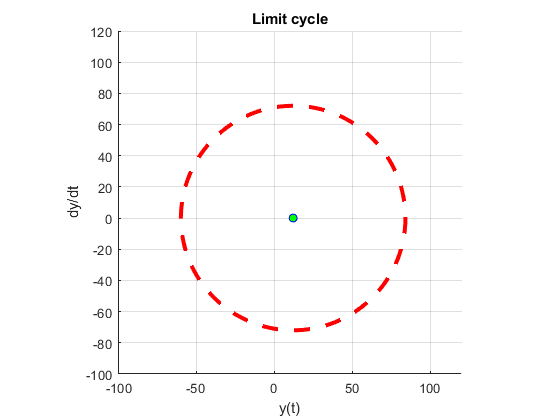

% Points 7-8
time=[0:0.01:2*pi];

grid on
hold on
limit = plot(y(time), dy(time), 'r--', "LineWidth",3);
center = plot(12,0, 'bo', "MarkerFaceColor",'g');
axis equal
axis([-100, 120, -100, 120])
xlabel("y(t)");
ylabel("dy/dt");
title("Limit cycle");

## Points 9-10

clc, clear, close all
syms x(t) y(t);
xm=[x;y];
x0=[-0.28;0.00];
time = [0,8];
sol = ode45(@diffeq65,time,x0)

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

c = 2.8274

sol = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [1×79 double]
          y: [2×79 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


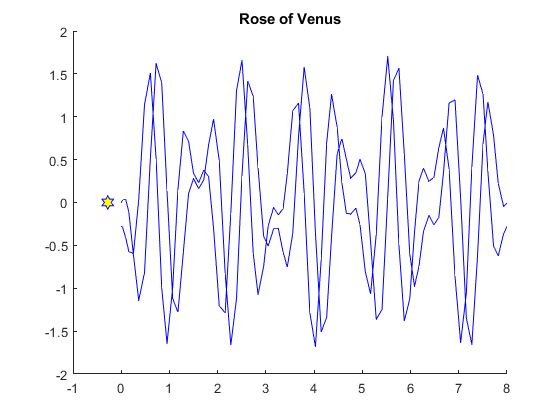

hold on
plot(sol.x, sol.y, 'b')
plot(-0.28, 0, "bh", "MarkerSize",10,"MarkerFaceColor",'y');
title("Rose of Venus")

## Part C

## Points 1-10

clc, clear, close all
syms Y t s;
y0=-60;dy0=0;
f=12+12*sin(t)

$$f = 12\,\sin\left(t\right)+12$$


% Point 1
F=laplace(f)

$$F = \frac{12}{s^{2}+1}+\frac{12}{s}$$


d2Y = s*s*Y-s*y0-dy0

$$d2Y = Y\,s^{2}+60\,s$$

dY = (1/6)*(s*Y - y0)

$$dY = \frac{Y\,s}{6}+10$$

LTofDE = d2Y + dY + Y == F

$$LTofDE = Y+60\,s+\frac{Y\,s}{6}+Y\,s^{2}+10=\frac{12}{s^{2}+1}+\frac{12}{s}$$

Sol = solve(LTofDE, Y)

$$Sol = -\frac{60\,s^{2}-12}{s^{3}+s}$$

Y = matlabFunction(Sol); 
% Point 2
Y(s);
% Point 3
PF = partfrac(Y(s))

$$PF = \frac{12}{s}-\frac{72\,s}{s^{2}+1}$$

% Point 4
limit(Y(s),s,inf)

$$ans = 0$$

% Point 5
y=ilaplace(Y(s))

$$y = 12-72\,\cos\left(t\right)$$

% Point 6
dy = matlabFunction(simplify(diff(y,t)))

dy = function_handle with value:
    @(t)sin(t).*7.2e+1


y=matlabFunction(y)

y = function_handle with value:
    @(t)cos(t).*-7.2e+1+1.2e+1


% Points 7-8
time=[0:0.05:2*pi];
grid on
hold on
limit = plot(y(time), dy(time), 'r.', "LineWidth",3);
center = plot(12,0, 'bo', "MarkerFaceColor",'g', "MarkerSize",10);
axis equal
axis([-100, 120, -100, 120])
xlabel("y(t)");
ylabel("dy/dt");
title("Limit Cycle")

% Points 9-10
clear
grid off
syms Y t s;
y0=0;dy0=0;
f=12+12*sin(t)

$$f = 12\,\sin\left(t\right)+12$$


F=laplace(f)

$$F = \frac{12}{s^{2}+1}+\frac{12}{s}$$

d2Y = s*s*Y-s*y0-dy0

$$d2Y = Y\,s^{2}$$

dY = (1/6)*(s*Y - y0)

$$dY = \frac{Y\,s}{6}$$

LTofDE = d2Y + dY + Y == F

$$LTofDE = Y\,s^{2}+\frac{Y\,s}{6}+Y=\frac{12}{s^{2}+1}+\frac{12}{s}$$

Sol = solve(LTofDE, Y)

$$Sol = \frac{\frac{12}{s^{2}+1}+\frac{12}{s}}{s^{2}+\frac{s}{6}+1}$$

Y = matlabFunction(Sol); 
Y(s);
PF = partfrac(Y(s))

$$PF = \frac{12}{s}-\frac{72\,s}{s^{2}+1}+\frac{360\,s+60}{6\,s^{2}+s+6}$$

limit(Y(s),s,inf)

$$ans = 0$$

y=ilaplace(Y(s))

$$y = 60\,{\mathrm{e}}^{-\frac{t}{12}}\,\left(\cos\left(\frac{\sqrt{143}\,t}{12}\right)+\frac{\sqrt{143}\,\sin\left(\frac{\sqrt{143}\,t}{12}\right)}{143}\right)-72\,\cos\left(t\right)+12$$

dy = matlabFunction(simplify(diff(y,t)))

dy = function_handle with value:
    @(t)sin(t).*7.2e+1-sqrt(1.43e+2).*exp(t.*(-1.0./1.2e+1)).*sin((sqrt(1.43e+2).*t)./1.2e+1).*(7.2e+2./1.43e+2)


y=matlabFunction(y)

y = function_handle with value:
    @(t)cos(t).*-7.2e+1+exp(t.*(-1.0./1.2e+1)).*(cos((sqrt(1.43e+2).*t)./1.2e+1)+(sqrt(1.43e+2).*sin((sqrt(1.43e+2).*t)./1.2e+1))./1.43e+2).*6.0e+1+1.2e+1


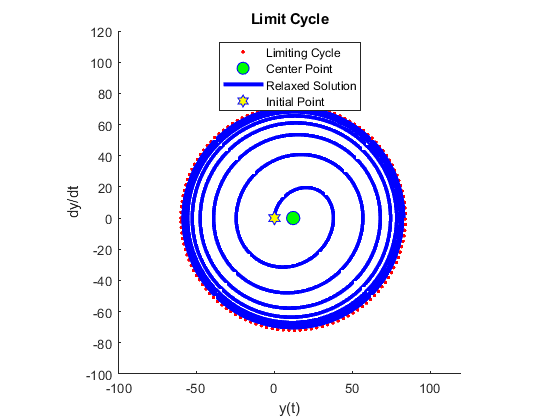

time=[0:0.01:15*pi];
rel = plot(y(time), dy(time),'b', "LineWidth",3);
ip = plot(0,0, 'bh', "MarkerFaceColor",'y', "MarkerSize",10);

legend(["Limiting Cycle","Center Point","Relaxed Solution","Initial Point"],"Location","north");

## Part D

% Points 1-5
clc, clear, close all
syms s t;
Re = 1.00; Rv = 0.72;       % in astronomical units
we = 2*pi; wv = 2*pi *13/8; % angular frequencies for Earth and Venus
c = (wv - we) * Rv % 2.8274

c = 2.8274


A=[0,-2*pi;2*pi,0];
f=c*[-1*sin(wv*t);cos(wv*t)];
x0=[-0.28;0.00];

% Point 1
R = inv(s*eye(2)-A)

$$R = \left(\begin{array}{cc} \frac{s}{s^{2}+4\,\pi^{2}} & -\frac{2\,\pi }{s^{2}+4\,\pi^{2}}\\ \frac{2\,\pi }{s^{2}+4\,\pi^{2}} & \frac{s}{s^{2}+4\,\pi^{2}} \end{array}\right)$$

% Point 2
F = laplace(f)

$$F = \left(\begin{array}{c} -\frac{117\,\pi^{2}}{40\,\left(s^{2}+\frac{169\,\pi^{2}}{16}\right)}\\ \frac{9\,\pi \,s}{10\,\left(s^{2}+\frac{169\,\pi^{2}}{16}\right)} \end{array}\right)$$

% Point 3
xzi = R*x0

$$xzi = \left(\begin{array}{c} -\frac{7\,s}{25\,\left(s^{2}+4\,\pi^{2}\right)}\\ -\frac{14\,\pi }{25\,\left(s^{2}+4\,\pi^{2}\right)} \end{array}\right)$$

% Point 4
xzs = simplify(R*F)

$$xzs = \left(\begin{array}{c} -\frac{189\,s\,\pi^{2}}{40\,\left(s^{2}+4\,\pi^{2}\right)\,\left(s^{2}+\frac{169\,\pi^{2}}{16}\right)}\\ -\frac{36\,\pi \,\left(13\,\pi^{2}-2\,s^{2}\right)}{5\,\left(16\,s^{4}+233\,\pi^{2}\,s^{2}+676\,\pi^{4}\right)} \end{array}\right)$$

% Point 5
X=xzi+xzs

$$X = \begin{array}{l} \left(\begin{array}{c} -\frac{7\,s}{25\,\sigma_{1}}-\frac{189\,s\,\pi^{2}}{40\,\sigma_{1}\,\left(s^{2}+\frac{169\,\pi^{2}}{16}\right)}\\ -\frac{14\,\pi }{25\,\sigma_{1}}-\frac{36\,\pi \,\left(13\,\pi^{2}-2\,s^{2}\right)}{5\,\left(16\,s^{4}+233\,\pi^{2}\,s^{2}+676\,\pi^{4}\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=s^{2}+4\,\pi^{2} \end{array}$$

x=matlabFunction(ilaplace(X))

x = function_handle with value:
    @(t)[-cos(t.*pi.*2.0)+cos(t.*pi.*(1.3e+1./4.0)).*(1.8e+1./2.5e+1);-sin(t.*pi.*2.0)+sin(t.*pi.*(1.3e+1./4.0)).*(1.8e+1./2.5e+1)]


x(4)

ans =    -1.7200
   -0.0000
